# UAV Selection Based on Harmonic Mean

clc
clear all
close all

## Initialization

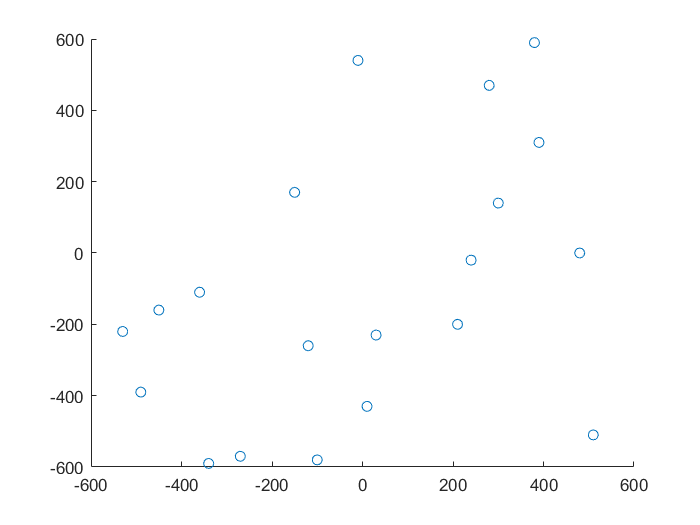

num_bit = 1;
UAV_N = 20;
freq = 2e09; % GHz
gamma_NF = [1:15];

m_AU = 2;
omega_AU = 1;
m_UB = 1;
omega_UB = 2;

fading_AU = random('nakagami', m_AU, omega_AU, [1, num_bit]);
fading_UB = random('nakagami', m_UB, omega_UB, [1, num_bit]);

pl_exponent = 2; % for LOS
dist = 20; % meter
path_loss = ((3e08/(4*pi*freq))^2) * dist^(-pl_exponent);

GU_A_coor = [-600, 0, 0];
GU_B_coor = [+600, 0, 0];
UAV_H = 100; % meter

% Way 1
% UAVs_coor = reshape(601 - randperm(1201, UAV_N*2), [UAV_N, 2]);

% Way 2
coor = [-590:10:590];
UAVs_coor = reshape(coor(randperm(size(coor,2), UAV_N*2)), [UAV_N, 2]);

UAVs_coor = cat(2, UAVs_coor, repmat(UAV_H, [UAV_N, 1]));
figure()
scatter(UAVs_coor(:,1), UAVs_coor(:,2))

## Selection of UAVs

## Calculate Throughput of Selected UAV

## Plot System model with UAVs

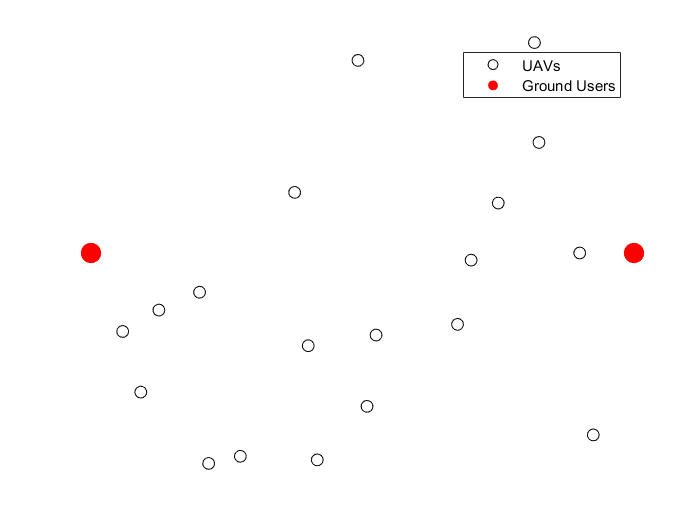

figure()
scatter(UAVs_coor(:,1), UAVs_coor(:,2), 50, 'black')
hold on
GU_coor = cat(1, GU_A_coor, GU_B_coor);
scatter(GU_coor(:,1), GU_coor(:,2), 150, 'red', 'filled')
axis off
legend('UAVs', 'Ground Users')